% ROSBag file processing
close all
clear

bag = rosbag('bag/twoboat_test7.bag');
topics = bag.AvailableTopics;

rabbit = select(bag,'Topic','april_cube/rabbit');
boat0 = select(bag,'Topic','/robot0/sandwich_0/sensors/p3d');
boat1 = select(bag,'Topic','/robot1/sandwich_1/sensors/p3d');


rabbitTs = timeseries(rabbit);
boat0Ts = timeseries(boat0);
boat1Ts = timeseries(boat1);

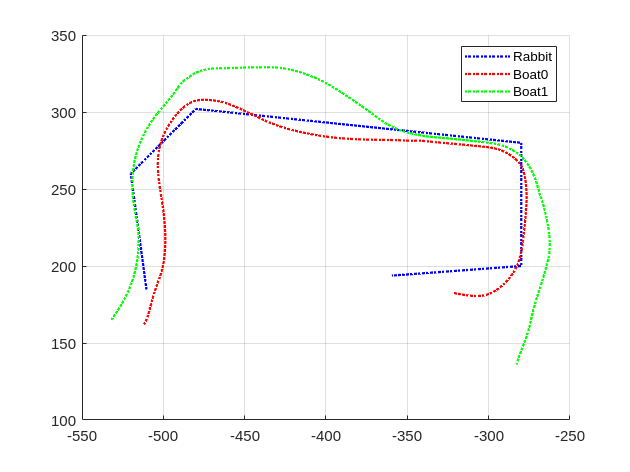

% Rabbit Position Data
rabbit_time = rabbitTs.Time;
rabbit_X = rabbitTs.Data(:,4);
rabbit_Y = rabbitTs.Data(:,5);


figure(1)
clf
grid on
hold on
plot(rabbit_X, rabbit_Y','b:','LineWidth',1.5)

% Boat Position Data
boat0_X = boat0Ts.Data(:,4);
boat0_Y = boat0Ts.Data(:,5);

boat1_X = boat1Ts.Data(:,4);
boat1_Y = boat1Ts.Data(:,5);

plot(boat0_X,boat0_Y,'r:','LineWidth',1.5)
plot(boat1_X,boat1_Y,'g:','LineWidth',1.5)
legend('Rabbit','Boat0','Boat1','Location','best')

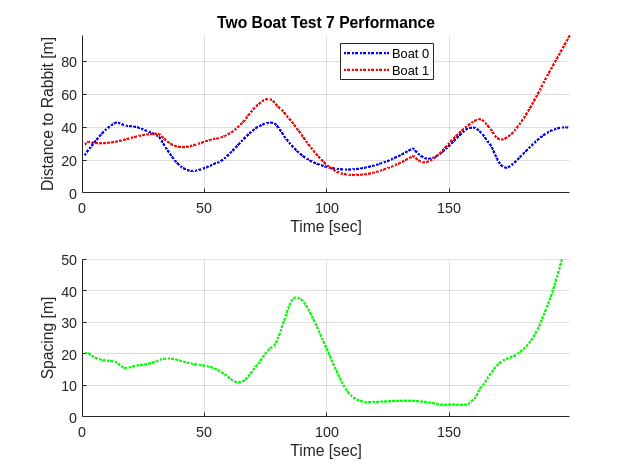

% Inter-vehicle spacing and distance to target
target0 = ((rabbit_X - boat0_X(1:end-1)).^2 + (rabbit_Y - boat0_Y(1:end-1)).^2).^0.5;
figure(2)
clf
subplot(2,1,1)
grid on
hold on
title('Two Boat Test 7 Performance')
plot(rabbit_time,target0,'b:','LineWidth',1.5)
ylabel('Distance to Rabbit [m]')
xlabel('Time [sec]')

target1 = ((rabbit_X - boat1_X(1:end-1)).^2 + (rabbit_Y - boat1_Y(1:end-1)).^2).^0.5;
plot(rabbit_time,target1,'r:','LineWidth',1.5)
axis([0 rabbit_time(end) 0 max(max(target1),max(target0))])
legend('Boat 0','Boat 1','Location','best')
subplot(2,1,2)
grid on
hold on
spacing = ((boat0_X - boat1_X).^2 + (boat0_Y - boat1_Y).^2).^0.5;
plot(rabbit_time,spacing(1:end-1),'g:','LineWidth',1.5)
axis([0 rabbit_time(end) 0 50])
ylabel('Spacing [m]')
xlabel('Time [sec]')